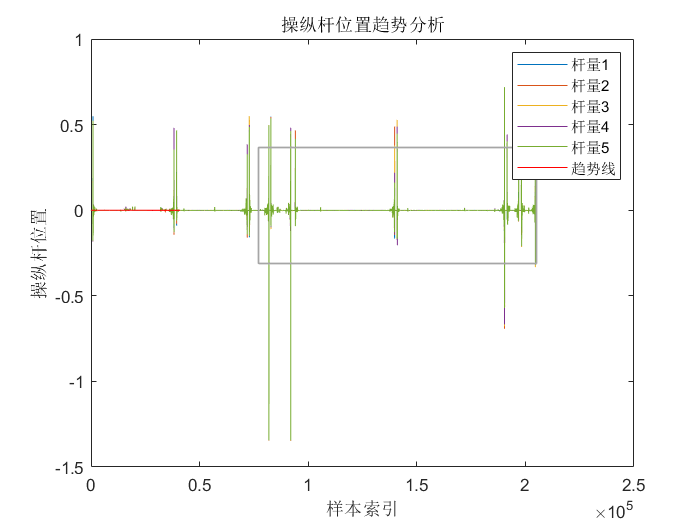


% 提取杆量数据
stick_position = OneData(:, 1:5); % 操纵杆位置数据，假设在第1列到第5列

% 滑动窗口参数
window_size = 5; % 滑动窗口大小，表示每秒记录的次数
stride = 1; % 滑动窗口的步长

% 初始化趋势线系数矩阵
order = 1; % 多项式拟合的阶数，这里选择1表示线性拟合
coeffs = zeros(order + 1, size(stick_position, 2)); % 初始化系数矩阵

% 滑动窗口趋势分析
for i = 1:size(stick_position, 2)
    for j = 1:stride:(size(stick_position, 1) - window_size + 1)
        window_data = stick_position(j:(j + window_size - 1), i); % 提取滑动窗口内的数据
        time = (j:(j + window_size - 1)) / window_size; % 时间，假设每秒记录5次
        coeffs(:, i) = coeffs(:, i) + polyfit(time, window_data, order)'; % 对滑动窗口内的数据进行多项式拟合并累加系数
    end
    coeffs(:, i) = coeffs(:, i) / ((size(stick_position, 1) - window_size + 1) / stride); % 求平均系数
end

% 数据可视化
figure;
plot(stick_position);
xlabel('样本索引');
ylabel('操纵杆位置');
title('操纵杆位置趋势分析');

% 绘制趋势线
hold on;
for i = 1:size(stick_position, 2)
    time = (1:size(stick_position, 1)) / window_size; % 计算时间
    y_fit = polyval(coeffs(:, i), time); % 计算拟合后的值
    plot(time, y_fit, 'r'); % 绘制趋势线
end
legend('杆量1', '杆量2', '杆量3', '杆量4', '杆量5', '趋势线');